plot(REDvoltage,REDcurrent,'.')
hold on,


%%CREATING ERRORBARS
xneg=0.001.*[1 1 1 1 1 1 1 1 1];
xpos=xneg;
yneg=(0.2e-14).*[1 1 1 1 1 1 1 1 1];
ypos=yneg;
errorbar(REDvoltage,REDcurrent,yneg,ypos,xneg,xpos,'o')


%%NEGATIVE SIDE FIT
%Linear model Poly1:
 %    f(x) = p1*x + p2
%Coefficients:
 %      p1 =      -4e-14
  %     p2 =     1.4e-14

%Goodness of fit:
 % SSE: 3.796e-59
  %R-square: 1
  %Adjusted R-square: NaN
 % RMSE: NaN
  
   p1 =      -4e-14

p1 = -4.0000e-14

   p2 =     1.4e-14

p2 = 1.4000e-14

   f = p1*REDvoltage + p2

f = 	1.0e+-13 *

    0.1200    0.1000    0.0800    0.0600    0.0400    0.0200    0.0000   -0.0200   -0.0400


   plot(REDvoltage,f,'m')
   
   
 %%POSITIVE SIDE FIT
 %Linear model Poly1:
  %   g(x) = p3*x + p4
%Coefficients (with 95% confidence bounds):
 %      p3 =      -6.000e-14  (-7.184e-14, -4.816e-14) (\pm 0.592)
  %     p4 =   1.971e-14  (1.707e-14, 2.236e-14)       (\pm 0.132)

%Goodness of fit:
 % SSE: 7.429e-30
  %R-square: 0.9714
 % Adjusted R-square: 0.9656
  %RMSE: 1.219e-15
  
   p3 =      -6e-14 

p3 = -6.0000e-14

   p4 =   1.971e-14

p4 = 1.9710e-14

   g = p3*REDvoltage + p4

g = 	1.0e+-13 *

    0.1671    0.1371    0.1071    0.0771    0.0471    0.0171   -0.0129   -0.0429   -0.0729


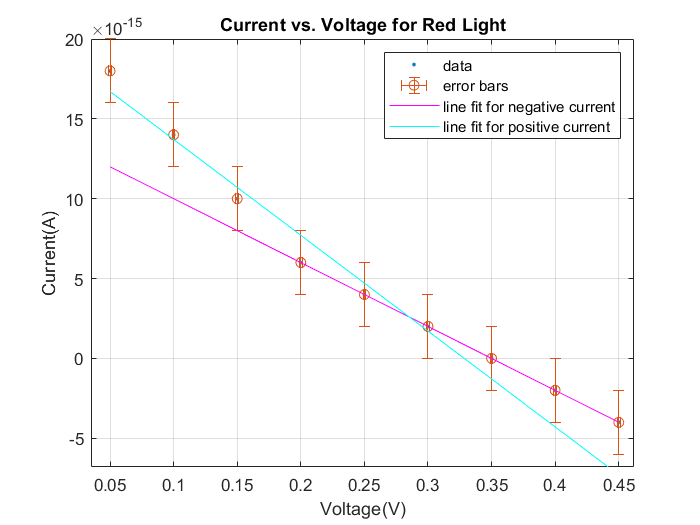

   plot(REDvoltage,g,'c')
   
   grid on
   title('Current vs. Voltage for Red Light')
xlabel('Voltage(V)')
ylabel('Current(A)')
legend({'data','error bars','line fit for negative current','line fit for positive current'})
xlim([0.035 0.462])
ylim([-0.0000000000000068 0.0000000000000200])